data = readtable('dataBenchmark.csv');

uEst = num2cell(data.uEst');
uVal = num2cell(data.uVal');
yEst = num2cell(data.yEst');
yVal = num2cell(data.yVal');

rng(42);
d1 = [1:10];
d2 = [1:5];
narx_net = narxnet(d1,d2,[4, 4]);
narx_net.divideFcn = '';
narx_net.trainParam.min_grad = 1e-10;
[p,Pi,Ai,t] = preparets(narx_net,uEst,{},yEst);

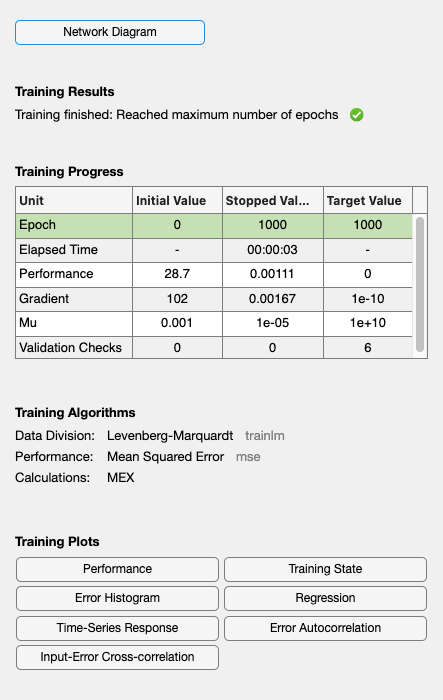

narx_net = train(narx_net,p,t,Pi);

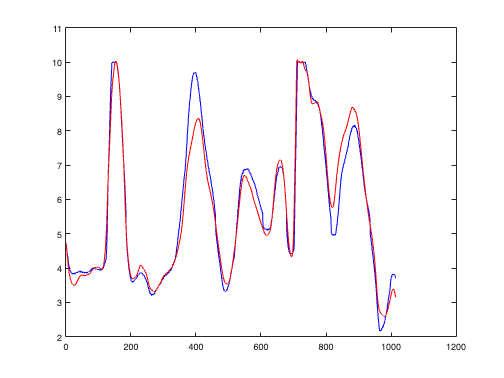

y1 = yVal(1:1024);
u1 = uVal(1:1024);
narx_net_closed = closeloop(narx_net);
[p1,Pi1,Ai1,t1] = preparets(narx_net_closed,u1,{},y1);
yp1 = narx_net_closed(p1,Pi1,Ai1);
TS = size(t1,2); 
plot(1:TS,cell2mat(t1),'b',1:TS,cell2mat(yp1),'r')

writecell(yp1', 'NARX_simulation.csv')